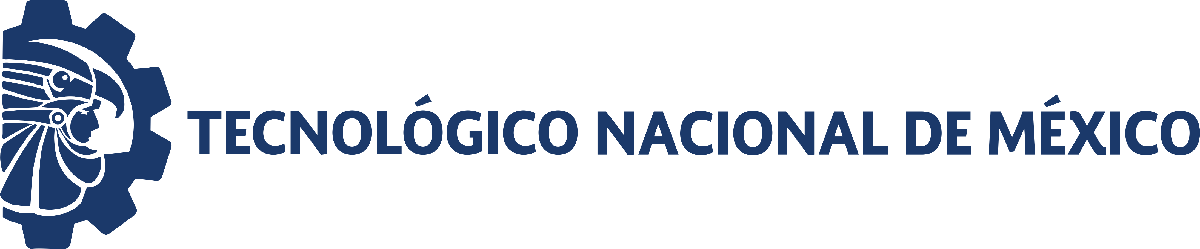                                 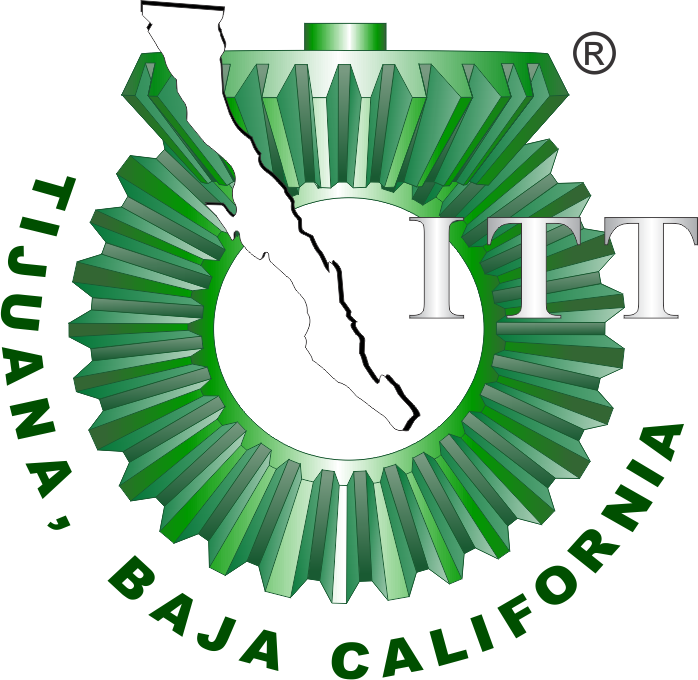

# Práctica tres: Modelado y control del sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

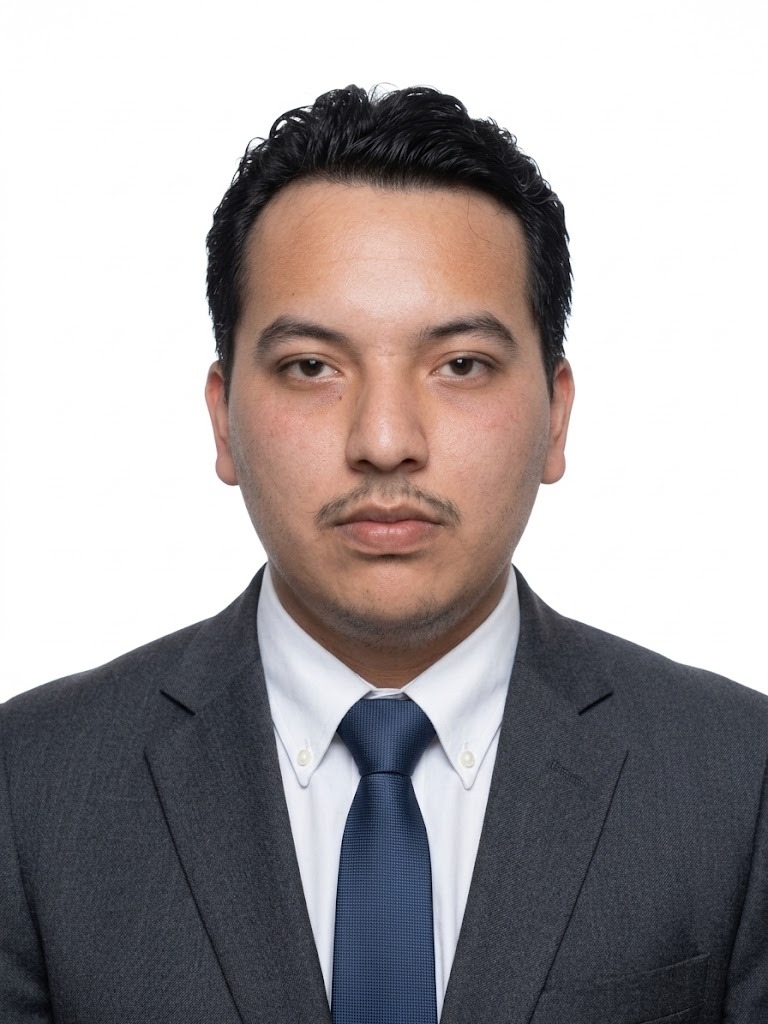

Nombre del alumno: **Garcia Grijalva Armando**

Número de control: **23212195**

Correo institucional: **L23212195@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'SistemaP3'

file = 'SistemaP3'

open_system(file)
tend = '10';
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
% set_param('Sistema(P1)/Vs(t): CE/Vs','VectorFormat','1-D array');

## Respuesta al escalón

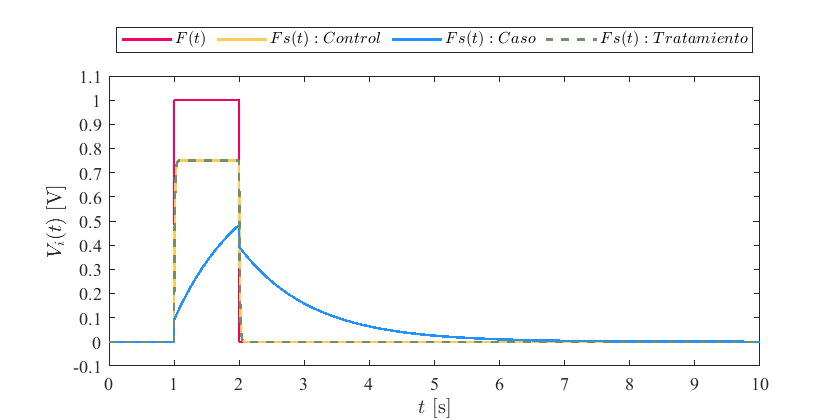

x = sim(file,parameters);
plotSignals(x.t,x.F,x.Fsx,x.Fsy,x.PID)

## Función: Respuestas de la simulación

function plotSignals(t,F,Fsx,Fsy,PID)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [247, 0, 99]/255;
    clr2 = [255, 203, 86]/255;
    clr3 = [35, 145, 255]/255;
    clr4 = [114, 142, 109]/255;
    order = [clr1;clr2;clr3;clr4]; colororder(order)
    
    plot(t,F,'-',t,Fsx,'-',t,Fsy,'-',t,PID,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));
    
    L = legend('$F(t)$','$Fs(t): Control$','$Fs(t): Caso$','$Fs(t): Tratamiento$');
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    
    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$V_i(t)$ [V]','interpreter','latex')
    
    xlim([0 10]); xticks(0:1:10)
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
    
    exportgraphics(gcf,['Señal_matlab.pdf'],'contenttype','vector')
end